%%HillClimb

clear;clc;close all;

x = randi([0,1],1,45);
n = 45;                         
max_iter = 10000;

history = zeros(1, max_iter);

for iter = 1:max_iter
    improved = false;
    for i = 1:n
        xn = x;
        xn(i) = 1 - xn(i);      
        if objective(xn) > objective(x)
            x = xn;
            improved = true;
            break;              
        end
    end
    
    history(iter) = objective(x);
 
    if ~improved
        break;                  
    end
end

fprintf('x: ')

x: 

fprintf('%d', x)

111001110101011011100100100001110011100011001

fprintf('fitness: ')

fitness: 

fprintf('%d', objective(x))

1002

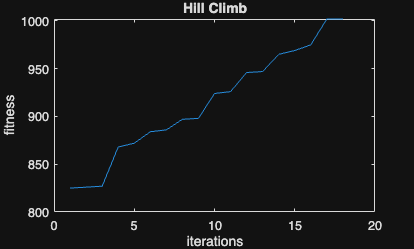



plot(1:iter, history(1:iter))
xlabel("iterations")
ylabel("fitness")
title("Hill Climb")

%% (mu,lambda) Evolution strategy

clear;clc;close all;


n = 45;          
max_iter = 1000;
mu = 50;
lambda = 100;
pm = 0.1;

pop = randi([0,1],mu,45);
history = zeros(1, max_iter);

for iter = 1:max_iter

    fit = arrayfun(@(i) objective(pop(i,:)), 1:mu);

    offspring = zeros(lambda, n);
    for j = 1:lambda
        parent = pop(randi(mu), :);

        mask = rand(1, n) < pm;
        offspring(j, :) = xor(parent, mask);
    end

    fit_off = arrayfun(@(i) objective(offspring(i,:)), 1:lambda);

    [~, idx] = sort(fit_off, 'descend');
    pop = offspring(idx(1:mu), :);

    history(iter) = max(fit_off);
end

fprintf('x: ')

x: 

fprintf('%d', pop(1,:))

100001101011001100010111100101000001101011111

fprintf('fitness: ')

fitness: 

fprintf('%d', objective(pop(1, :)))

1001

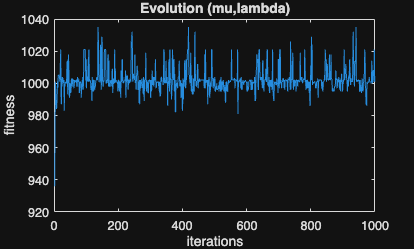



plot(1:iter, history(1:iter))
xlabel("iterations")
ylabel("fitness")
title("Evolution (mu,lambda)")

%% (mu+lambda) Evolution strategy

clear;clc;close all;

n = 45;          
max_iter = 1000;
mu = 50;
lambda = 100;
pm = 0.1;

pop = randi([0,1],mu,45);
history = zeros(1, max_iter);

for iter = 1:max_iter

    fit = arrayfun(@(i) objective(pop(i,:)), 1:mu);

    offspring = zeros(lambda, n);
    for j = 1:lambda
        parent = pop(randi(mu), :);

        mask = rand(1, n) < pm;
        offspring(j, :) = xor(parent, mask);
    end

    fit_off = arrayfun(@(i) objective(offspring(i,:)), 1:lambda);

    union_pop = [pop; offspring];
    union_fit = [fit, fit_off];

    [~, idx] = sort(union_fit, 'descend');
    pop = union_pop(idx(1:mu), :);

    history(iter) = max(union_fit);
end

fprintf('x: ')

x: 

fprintf('%d', pop(1,:))

110111001000101110111111000000100010111001110

fprintf('fitness: ')

fitness: 

fprintf('%d', objective(pop(1, :)))

1035

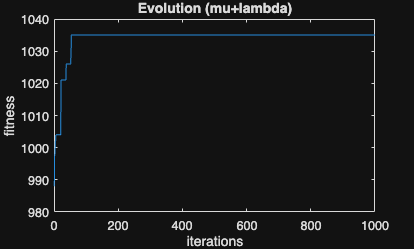


plot(1:iter, history(1:iter))
xlabel("iterations")
ylabel("fitness")
title("Evolution (mu+lambda)")